ieInit

## **Create a scene**

gridline scene

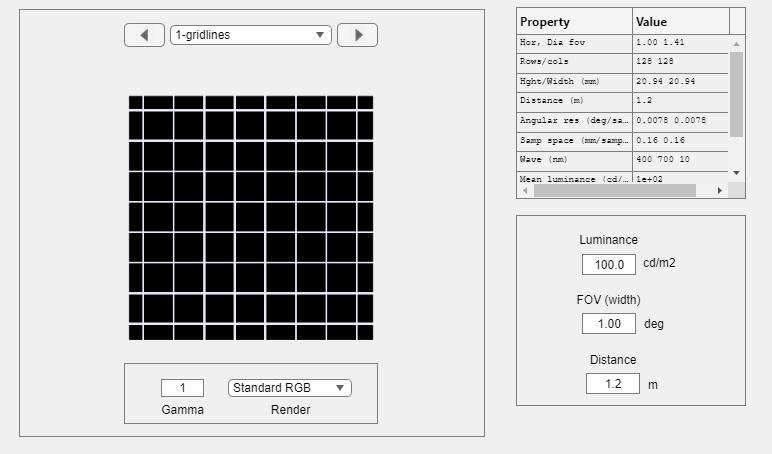

scene = sceneCreate('gridlines', 128);
scene = sceneSet(scene, 'h fov', 1);
scene = sceneSet(scene,'distance',1.2); %set distance from scene to optics in meters
sceneWindow(scene);

image scene

% scene = sceneFromFile('eagle.jpg','rgb',100,'LCD-Apple');
% scene = sceneSet(scene,'h fov',10);
% scene = sceneSet(scene,'distance',1.2);
% sceneWindow(scene);

## Create vertical pupil aperture 

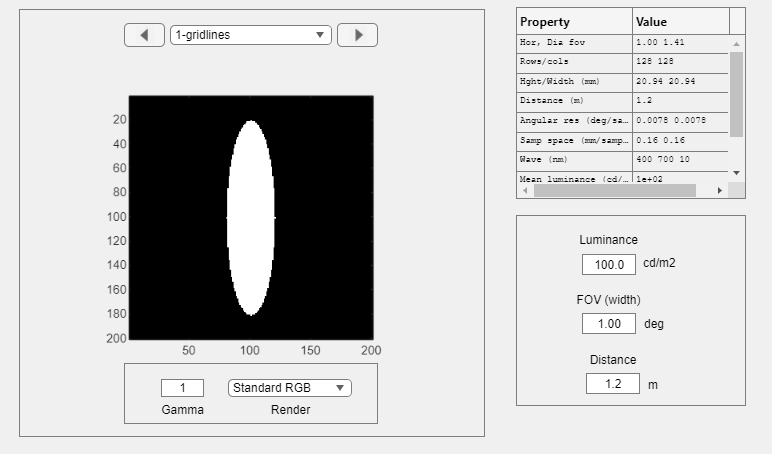


% Create a 201x201 matrix filled with zeros
im = zeros(201, 201);

% Define the center and the semi-axes of the ellipse
center = [101, 101]; % Center of the matrix
semi_major_axis = 80; % Vertical radius
semi_minor_axis = 20; % Horizontal radius

% Loop through each element of the matrix
for i = 1:201
    for j = 1:201
        % Calculate the distance from the center using the ellipse equation
        distance = ((i - center(1))^2 / semi_major_axis^2) + ((j - center(2))^2 / semi_minor_axis^2);
        % If the distance is less than or equal to 1, set the element to 1
        if distance <= 1
            im(i, j) = 1;
        end
    end
end

% Display the matrix as an image

imagesc(im); colormap(gray); axis image

### create a round pupil with the same size above

% % Calculate the area of the ellipse
% % ellipse_area = sum(im(:))
%  % ellipse_area = 10000
% % Create a new matrix "im2" for the round shape with the same area as "im"
% im2 = zeros(201, 201);
% 
% % Calculate the radius of the circle with the same area as the ellipse
% radius = sqrt(ellipse_area / pi);
% 
% % Loop through each element of the new matrix "im2"
% for i = 1:201
%     for j = 1:201
%         % Calculate the distance from the center
%         distance = sqrt((i - center(1))^2 + (j - center(2))^2);
% 
%         % If the distance is less than or equal to the radius, set the element to 1
%         if distance <= radius
%             im2(i, j) = 1;
%         end
%     end
% end
% imagesc(im2); colormap(gray); axis image




## create multiple-slit pupil 

% % Create a 201x201 matrix filled with zeros
% im = zeros(201, 201);
% 
% % Define the number of slits, their width, and their length
% num_slits = 3;
% slit_width = 50;
% slit_length = 10; % Change this value to adjust the length of the slits
% 
% % Calculate the spacing between slits
% spacing = floor((201 - num_slits * slit_width) / (num_slits + 1));
% 
% % Loop through each slit
% for k = 1:num_slits
%     % Calculate the starting and ending columns for the current slit
%     start_col = (k - 1) * (slit_width + spacing) + spacing + 1;
%     end_col = start_col + slit_width - 1;
% 
%     % Calculate the starting and ending rows for the current slit
%     start_row = floor((201 - slit_length) / 2) + 1;
%     end_row = start_row + slit_length - 1;
% 
%     % Fill the current slit with ones
%     im(start_row:end_row, start_col:end_col) = 1;
% end
% 
% % Display the matrix as an image
% imshow(im, []);


## Convert aperture image and scene into Optical image 

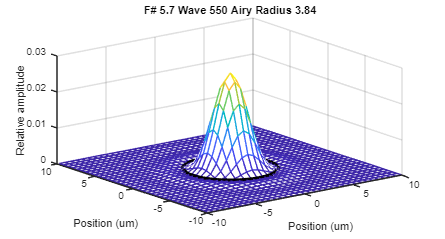


%apply the pupil function to wavefront and show the point spread function
wvf = wvfCreate;
wvf = wvfCompute(wvf);
wvfPlot(wvf,'psf','unit','um','plot range',10,'airydisk',true);

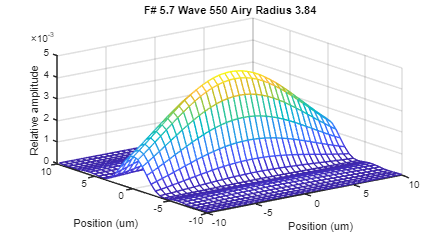


wvf = wvfCompute(wvf,"aperture",im); 
wvfPlot(wvf,'psf','unit','um','plot range',10, 'airydisk',true);

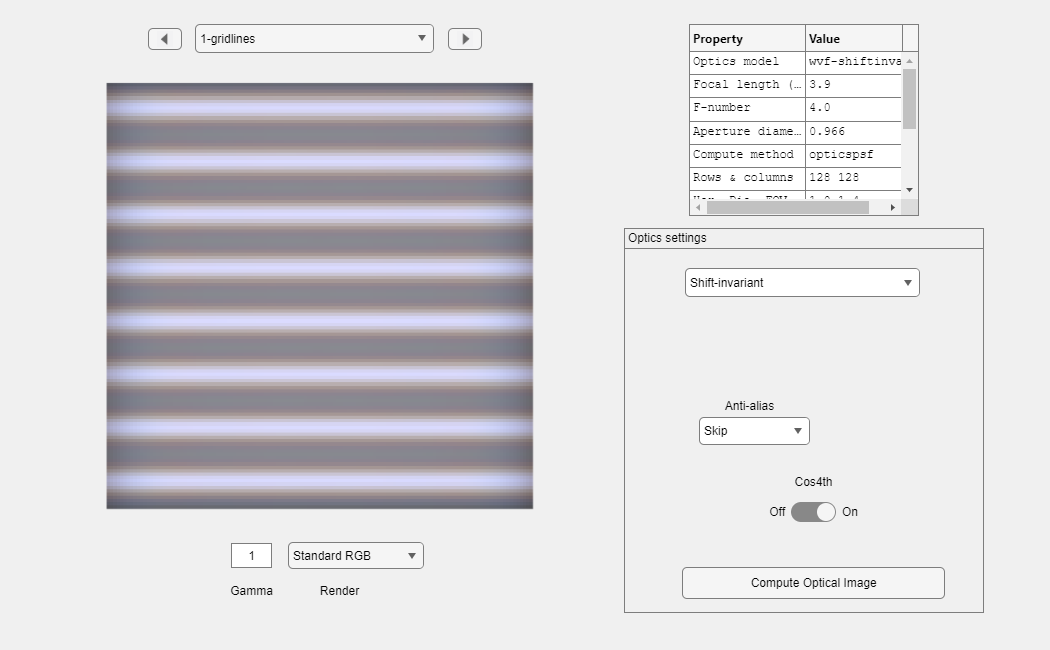

%wvfSummarize(wvf);

oi = oiCreate('wvf');
oi = oiCompute(oi, scene,'crop',true,'aperture',im);
oiWindow(oi);

## cMosaic to build cone mosaic

#### Generate the mosaic

positionDegs = [0 0];
sizeDegs = [0.3 0.3];
cm = cMosaic('size degs', sizeDegs, ...         % SIZE: 1.0 degs (x) 0.5 degs (y)
    'position degs', positionDegs, ... % ECC: (0,0)
    'ecc varying cone blur', true ...
    );

Loading cone mosaic data from C:\Users\leiyu\OneDrive - KLA Corporation\Documents\GitHub\isetbio\isettools\ganglioncells\data\lattices\right_eye_cones_58deg_mosaic.
Cache is not valid. Recomputing cone aperture zones.


#### Visualize of the mosaic 

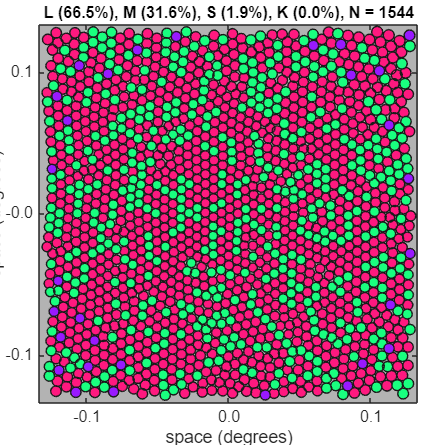

cm.visualize();

## Compute a single noise free instance and view it

allE   = cm.compute(oi);    % Compute all the excitations

Cache is not valid. Recomputing cone aperture zones.
Using 2 blur zones


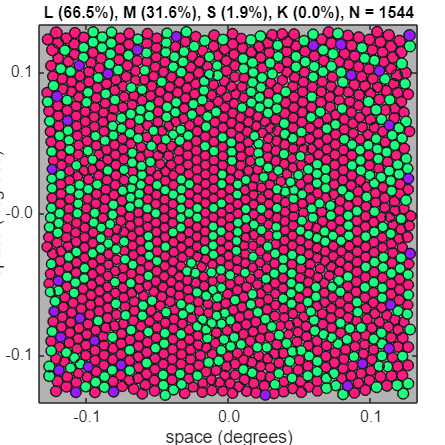

vParms = cm.visualize();    % Visualize the mosaic

## Line plots

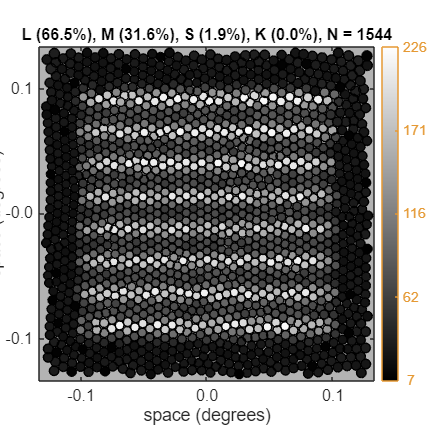

% Create an image of the excitations
cm.plot('excitations',allE);

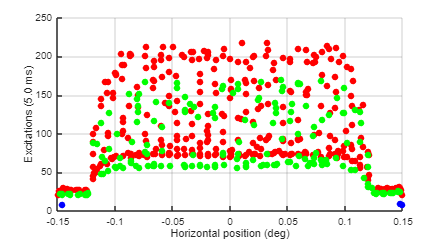


% Plot the excitations along a horizontal line
cm.plot('excitations horizontal line',allE, 'y deg',0);

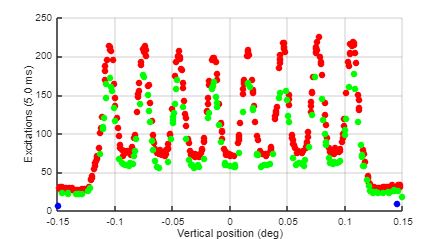

cm.plot('excitations vertical line',allE, 'x deg',0);

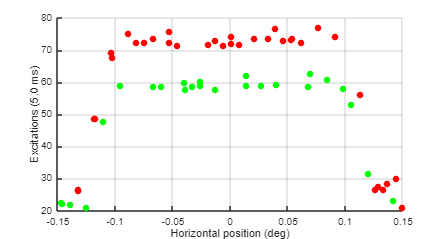


% Set the thickness of the horizontal line
cm.plot('excitations horizontal line',allE, 'y deg',0,'thickness',0.01);

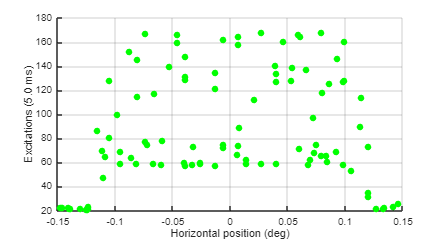

cm.plot('excitations horizontal line',allE, 'y deg',0,'thickness',0.05, 'conetype','m');

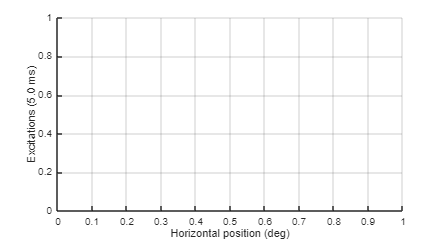

cm.plot('excitations horizontal line',allE, 'y deg',0,'thickness',0.05, 'conetype','s');